clc, clear all;
size = 40;  % 图片大小

## 加载图片

imds = imageDatastore("E:\GIT_repository\Homework_to_finish\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data", "IncludeSubfolders", true, "LabelSource", "foldernames")

imds =   ImageDatastore - 属性:

                       Files: {
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\0\0_0000.jpg';
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\0\0_0001.jpg';
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\0\0_0002.jpg'
                               ... and 16148 more
                              }
                     Folders: {
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data'
                              }
                      Labels: [0; 0; 0 ... and 16148 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastor

imds = shuffle(imds)

imds =   ImageDatastore - 属性:

                       Files: {
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\5\5_0681.jpg';
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\V\V_0060.jpg';
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data\hu\hu_0060.jpg'
                               ... and 16148 more
                              }
                     Folders: {
                              ' ...\computer_vision\大作业 车牌识别\image_set\VehicleLicense\Data'
                              }
                      Labels: [5; V; hu ... and 16148 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatas

save("imds.mat", "imds")

## 设置验证集和训练集

[imdsTrain, imdsValidation, imdsTest] = splitEachLabel(imds, 0.6, 0.2, 0.2, 'randomized');
save("imdsTest.mat", "imdsTest")

## 修改图片的维度

augmenter = imageDataAugmenter('RandRotation',[-5 5],'RandXTranslation',[-5 5],'RandYTranslation',[-5 5]);
augimdsTrain = augmentedImageDatastore([size size], imdsTrain, "ColorPreprocessing", "rgb2gray", "DataAugmentation", augmenter)

augimdsTrain =   augmentedImageDatastore - 属性:

             NumObservations: 9692
                       Files: {9692×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'rgb2gray'
                  OutputSize: [40 40]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


augimdsValidation = augmentedImageDatastore([size size], imdsValidation, "ColorPreprocessing", "rgb2gray")

augimdsValidation =   augmentedImageDatastore - 属性:

             NumObservations: 3227
                       Files: {3227×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'rgb2gray'
                  OutputSize: [40 40]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## 创建层组

layers = [
    imageInputLayer([size size 1],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],32,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])

    convolution2dLayer([3 3],64,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],64,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool_2","Stride",[2 2])

    convolution2dLayer([3 3],128,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],128,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    maxPooling2dLayer([2 2],"Name","pool_3","Stride",[2 2])

    convolution2dLayer([3 3],256,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],256,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu4_2")
    maxPooling2dLayer([2 2],"Name","pool_4","Stride",[2 2])

    convolution2dLayer([3 3],256,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],256,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu5_2")
    maxPooling2dLayer([2 2],"Name","pool_5","Stride",[2 2])

    fullyConnectedLayer(2048,"Name","fc_1","WeightL2Factor",0)
    reluLayer("Name","relu_6")
    dropoutLayer(0.5,"Name","drop_1")

    fullyConnectedLayer(2048,"Name","fc_2","WeightL2Factor",0)
    reluLayer("Name","relu_7")
    dropoutLayer(0.5,"Name","drop_2")
    fullyConnectedLayer(65,"Name","fc_3")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## 绘制层

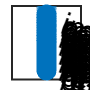

plot(layerGraph(layers));

## 定义训练选项

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs', 60, ...
    'MiniBatchSize', 128, ...
    "Shuffle", "every-epoch", ...
    "ValidationData", augimdsValidation, ...
    'ValidationFrequency', 20, ...
    'ExecutionEnvironment','gpu', ...
    'Verbose',false, ...
    'Plots','training-progress');

## 训练网络

% net = trainNetwork(augimdsTrain, layers, options);

## 保存网络参数

% save('myDNN_params.mat', 'net');